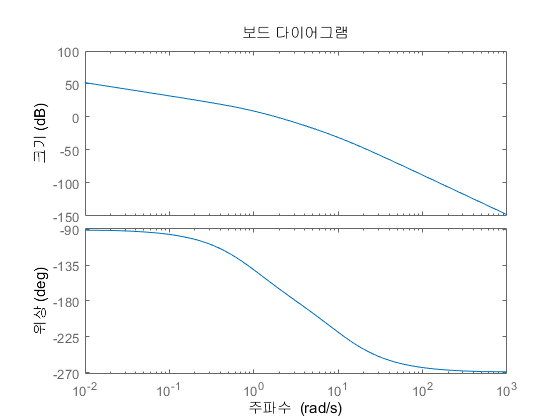

s = tf('s');
sys = 4/(s*(0.1*s+1)*(s+1));
bode(sys);

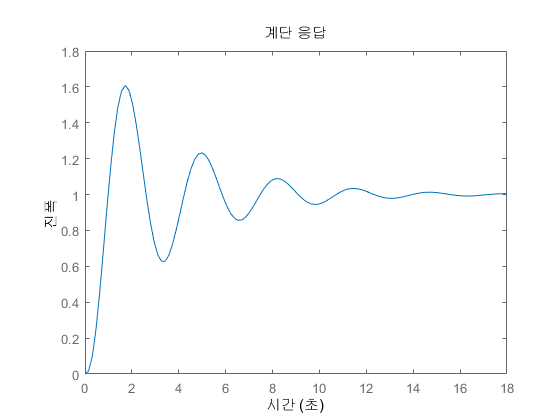

step(sys/(1+sys));

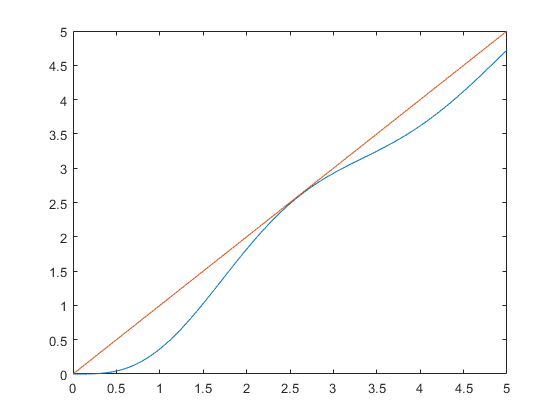

t = 0:0.01:5;
c1 = step(sys/(s*(1+sys)), t);
plot(t, c1, t, t);

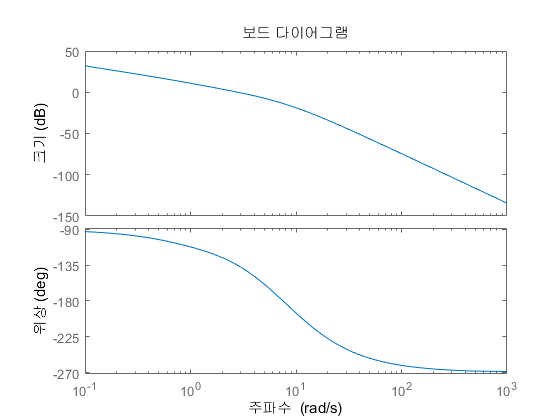

compSys = (s+1.28)/((s+6.1319)*0.21)* sys;
bode(compSys);

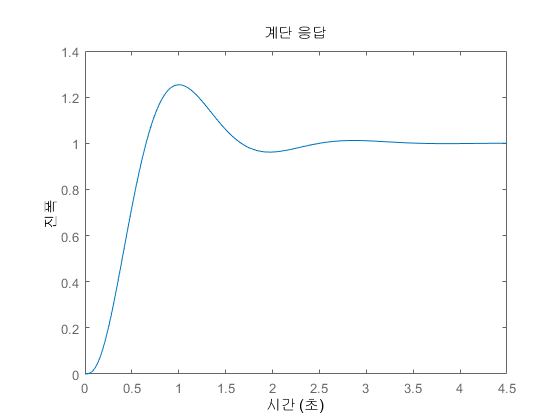

step(compSys/(1+compSys));

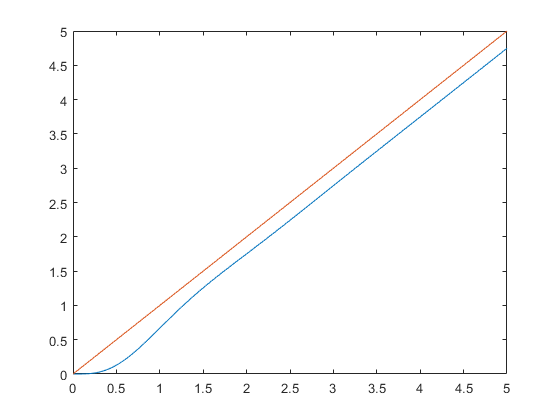

c2 = step(compSys/(s*(1+compSys)), t);
plot(t,c2,t,t);